addpath 'C:\GitHub\CVUT-MatLab\BnB'
clear;clc;startup;yalmip('clear')

Toolbox "yalmip:R20230609:all" added to the Matlab path.

The MATLAB interface for Gurobi 10.0.3 has been installed.

The directory
    C:\Program Files\MATLAB\Gurobi\win64\matlab\
has been added to the MATLAB path.
To use Gurobi regularly, you must save this new path definition.
To do this, type the command
    savepath
at the MATLAB prompt. Please consult the MATLAB documentation
if necessary.


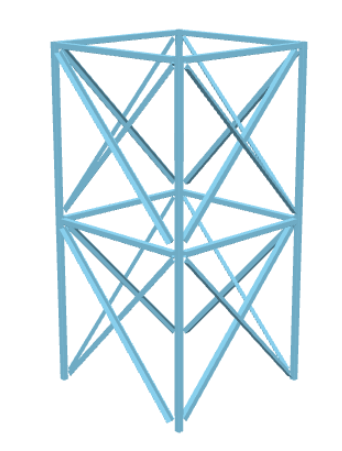

Sections = importdata("Sections.mat");
nRhs = numel(table2array(Sections.RHS(:,"A")));
crossSectionsSet.A = cat(1, table2array(Sections.RHS(:,"A")), table2array(Sections.L(:,"A")));
crossSectionsSet.I = cat(1, table2array(Sections.RHS(:,"Iy")), table2array(Sections.L(:,"Iv")));
na = numel(crossSectionsSet.A); 

## Ground structure

### Nodes

width = 2.9;
length = 2.9;
height = 3;
nbricks = 7;
nodes.x = kron(ones(nbricks+1,1),[0;length;length;0]);                            % x coordinates of nodes
nodes.y = kron(ones(nbricks+1,1),[0;0;width;width]);                              % y coordinates of nodes
nodes.z = kron([height;height;height;height], ones(nbricks+1, 1)) ...
        .* repelem((0:nbricks)', numel([height;height;height;height]), 1)  ;
nodes.z((nbricks)*4+1:(nbricks+1)*4) =[20;20;20;20]; % z coordinates of nodes
nnodes  = numel(nodes.x);                           % number of nodes

### Elements

elements.modulNodes1 = [1;2;3;4; 1;2;2;3;3;4;4;1; 5;6;7;8  ];   % elements starting nodes
elements.nodes1 = (reshape(kron(elements.modulNodes1', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(elements.modulNodes1))*4);
elements.modulNodes2 = [5;6;7;8; 6;5;7;6;8;7;5;8; 6;7;8;5  ];   % elements ending nodes
elements.nodes2 = (reshape(kron(elements.modulNodes2', ones(nbricks, 1))', 1, [])' ...
        + repelem((0:nbricks-1)', numel(elements.modulNodes2))*4);
nr = numel(elements.nodes1);  % number of elements  
modulElemGroup = [1;1;1;1; 2;2;2;2;2;2;2;2;    3;3;3;3];
elemGroup = reshape(kron(modulElemGroup', ones(nbricks, 1))', 1, [])';
ng = max(max(elemGroup));
Q = sparse(1:nr,elemGroup,1,nr,ng);
G = kron( Q, eye(na));

### Results

Plot the optimal design. Note that the dimensions are scaled.

SA_result = [9;6;36];
SAvectorX = zeros(189,1);
SAvectorX(SA_result(1)) = 1; 
SAvectorX(SA_result(2)+na) = 1; 
SAvectorX(SA_result(3)+2*na) = 1;
[eigSA,volumeSA] = towerStabFn(SA_result)

eigSA = 1.0131

volumeSA = 0.5163

BnB_result = [8;3;33];
BnBvectorX = zeros(189,1);
BnBvectorX(BnB_result(1)) = 1; 
BnBvectorX(BnB_result(2)+na) = 1; 
BnBvectorX(BnB_result(3)+2*na) = 1;
[eigBnB,volumeBnB] = towerStabFn(BnB_result)

eigBnB = -0.5831

volumeBnB = 0.3754

### Plotting SA

Plot the optimal design. Note that the dimensions are scaled.

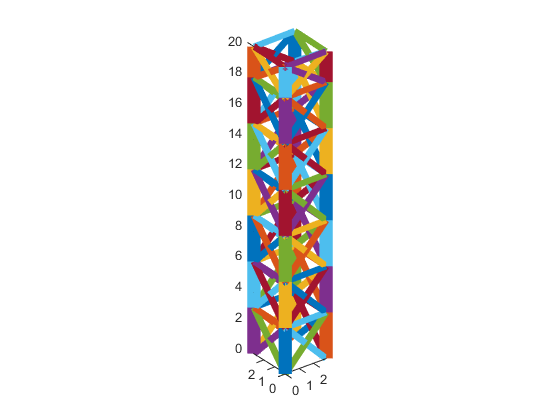

crossSectionsSA = reshape(G*SAvectorX, na, nr)'*crossSectionsSet.A;
crossSectionsBnB = reshape(G*BnBvectorX, na, nr)'*crossSectionsSet.A;
scale = max(max(value(crossSectionsSA)),max(value(crossSectionsBnB)));
nonzeroAreas = value(crossSectionsSA)>0;
p = plot3([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]',...
          [nodes.z(elements.nodes1(nonzeroAreas)) nodes.z(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSectionsSA(nonzeroAreas))/scale));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal

### Plotting BnB

Plot the optimal design. Note that the dimensions are scaled.

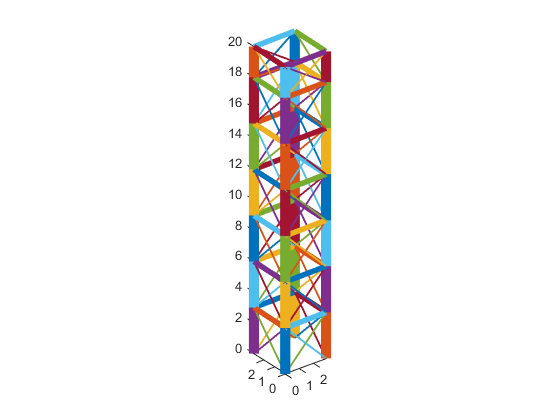

nonzeroAreas = value(crossSectionsBnB)>0;
p = plot3([nodes.x(elements.nodes1(nonzeroAreas)) nodes.x(elements.nodes2(nonzeroAreas))]',...
          [nodes.y(elements.nodes1(nonzeroAreas)) nodes.y(elements.nodes2(nonzeroAreas))]',...
          [nodes.z(elements.nodes1(nonzeroAreas)) nodes.z(elements.nodes2(nonzeroAreas))]');
set(p, {'LineWidth'}, num2cell(10*value(crossSectionsBnB(nonzeroAreas))/scale));
xlim([min(nodes.x)-0.1,max(nodes.x)+0.1]);  % To avoid tight limits
ylim([min(nodes.y)-0.1,max(nodes.y)+0.1]);  % To avoid tight limits
axis equal